heightmap=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\cable detection\exp0186\h_map\h_map_Exp186_0435.tif','r'));

Error using Tiff
Could not open file '\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\cable detection\exp0186\h_map\h_map_Exp186_0435.tif'.

Input some additional information here:

lengthunit_name = "pixel" %for example, "nm"

lengthunit_name = "pixel"

voxel_size_x = 1; 
voxel_size_y = 1;
voxel_size_z = 1; %in chosen length unit

tile_size= 180;

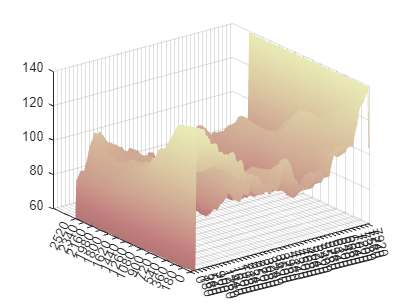

figure
mesh(heightmap);
zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;

Analysis for metric (first fundamental form) and metric determinant

[diff_x, diff_y] =gradient(double(h_smooth)); %central difference

Unrecognized function or variable 'h_smooth'.

gxx =  1+diff_x.^2;
gyy =  1+diff_y.^2;
gxy= diff_x.*diff_y;
sqrtg = sqrt(gxx.*gyy - gxy.^2);

imshow(sqrtg,[1,1.05]);

Unrecognized function or variable 'sqrtg'.

Try smoothin heightmap first.  Cell scale = 10 to 30 pixels.

h_smooth = imgaussfilt(double(heightmap), 5);

Unrecognized function or variable 'heightmap'.

figure
mesh(h_smooth);
zlim([60, 140]);
shading interp;
colormap(pink);
ax=gca;
ax.YTick = 0:tile_size:2560;
ax.XTick = 0:tile_size:7951;
axis equal

%need second derivatives
Gaussian_curvature = 0;